## Introduction

In this scrip, we just try to test the calcualtion of residual（残差）.

## Import data and previewing

data_name='n78_5s'

data_name = 'n78_5s'

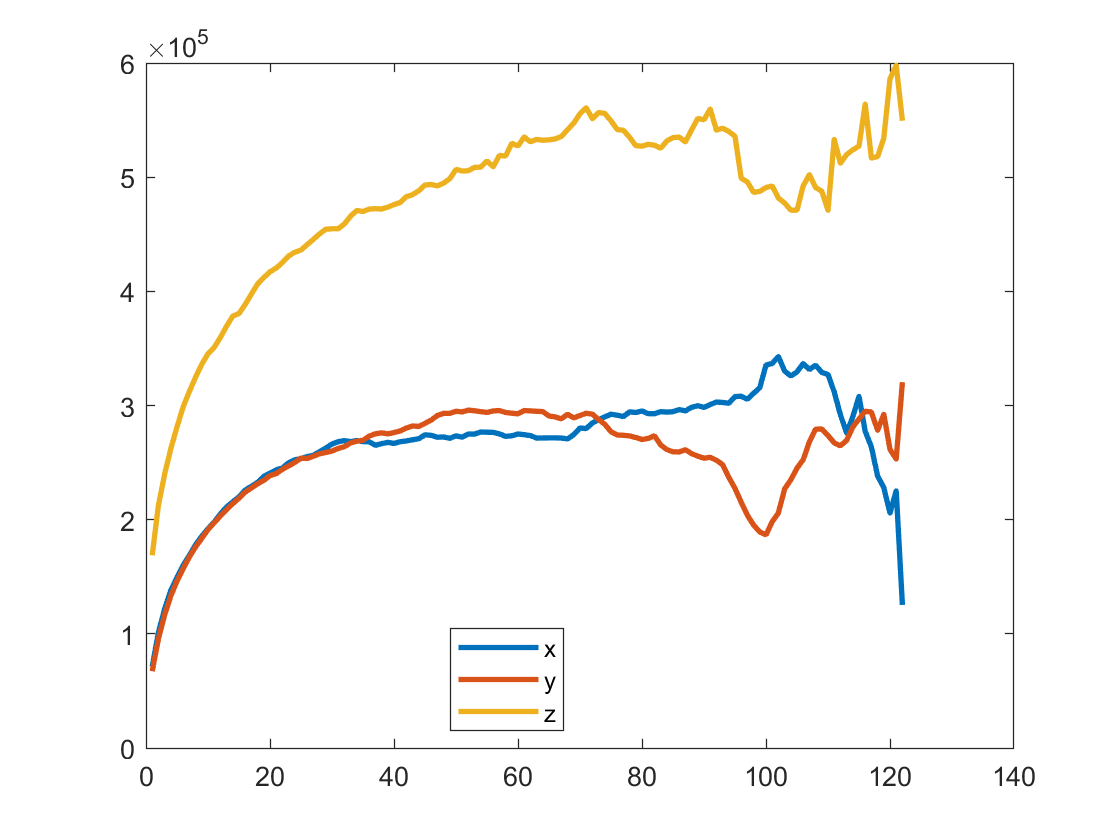

load(['C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\MSDData4Quan_20210905\MSD_',data_name,'_All.mat'])
plot(eval(['MSD_',data_name,'_All']).MSD_PP,'LineWidth',2)
legend('x','y','z','Location',"best");

cut down the declining part, we delete all data after the maximum one.

Reserved_length=zeros(3,1);
experiment_interval=5

experiment_interval = 5

X part

%experiment_MSDX=eval(['MSD_',data_name,'_All']).MSD_PP(:,1);
%max_experiment_MSDX=max(experiment_MSDX);
Reserved_length(1,1)=find(eval(['MSD_',data_name,'_All']).MSD_PP(:,1)==max(eval(['MSD_',data_name,'_All']).MSD_PP(:,1)));
interceptive_experiment_MSDX=eval(['MSD_',data_name,'_All']).MSD_PP(1:Reserved_length(1,1),1);

Y part

Reserved_length(2,1)=find(eval(['MSD_',data_name,'_All']).MSD_PP(:,2)==max(eval(['MSD_',data_name,'_All']).MSD_PP(:,2)));
interceptive_experiment_MSDY=eval(['MSD_',data_name,'_All']).MSD_PP(1:Reserved_length(2,1),2);

Z part

Reserved_length(3,1)=find(eval(['MSD_',data_name,'_All']).MSD_PP(:,3)==max(eval(['MSD_',data_name,'_All']).MSD_PP(:,3)))

Reserved_length =    102
   122
   121


interceptive_experiment_MSDZ=eval(['MSD_',data_name,'_All']).MSD_PP(1:Reserved_length,3);

## Data Importing

import parameters

m=1;%just for test
%zeta=
%psi=10;%psi=0---> no potential
%H=;
kB=1.3806505e-23;
T=300;

import Time interval

delta=0.01;

import Total Time

Tmax=Reserved_length(1,1)*experiment_interval;

import Total_experiment_number

Total_experiment_number=100;

## Fuction part

get GLE simulation

for H=0.7
    for zeta=50
        for psi=zeta/5
            simulation_RMSX=function_GLEsubdiffusion_fv0(m,kB,T,psi,zeta,H,delta, ...
                Tmax,Total_experiment_number);
            T_range = linspace(1,1001);

compare simulation with experiment data

progress rate  1 %
progress rate  2 %
progress rate  3 %
progress rate  4 %
progress rate  5 %
progress rate  6 %
progress rate  8 %
progress rate  9 %
progress rate  10 %
progress rate  11 %
progress rate  12 %
progress rate  13 %
progress rate  15 %
progress rate  16 %
progress rate  17 %
progress rate  18 %
progress rate  19 %
progress rate  20 %
progress rate  21 %
progress rate  22 %
progress rate  23 %
progress rate  24 %
progress rate  25 %
progress rate  26 %
progress rate  27 %
progress rate  30 %
progress rate  31 %
progress rate  32 %
progress rate  33 %
progress rate  34 %
progress rate  35 %
progress rate  36 %
progress rate  37 %
progress rate  38 %
progress rate  39 %
progress rate  40 %
progress rate  41 %
progress rate  42 %
progress rate  43 %
progress rate  44 %
progress rate  45 %
progress rate  46 %
progress rate  47 %
progress rate  48 %
progress rate  49 %
progress rate  50 %
progress rate  51 %
progress rate  52 %
progress rate  53 %
progress rate  54 %
progress

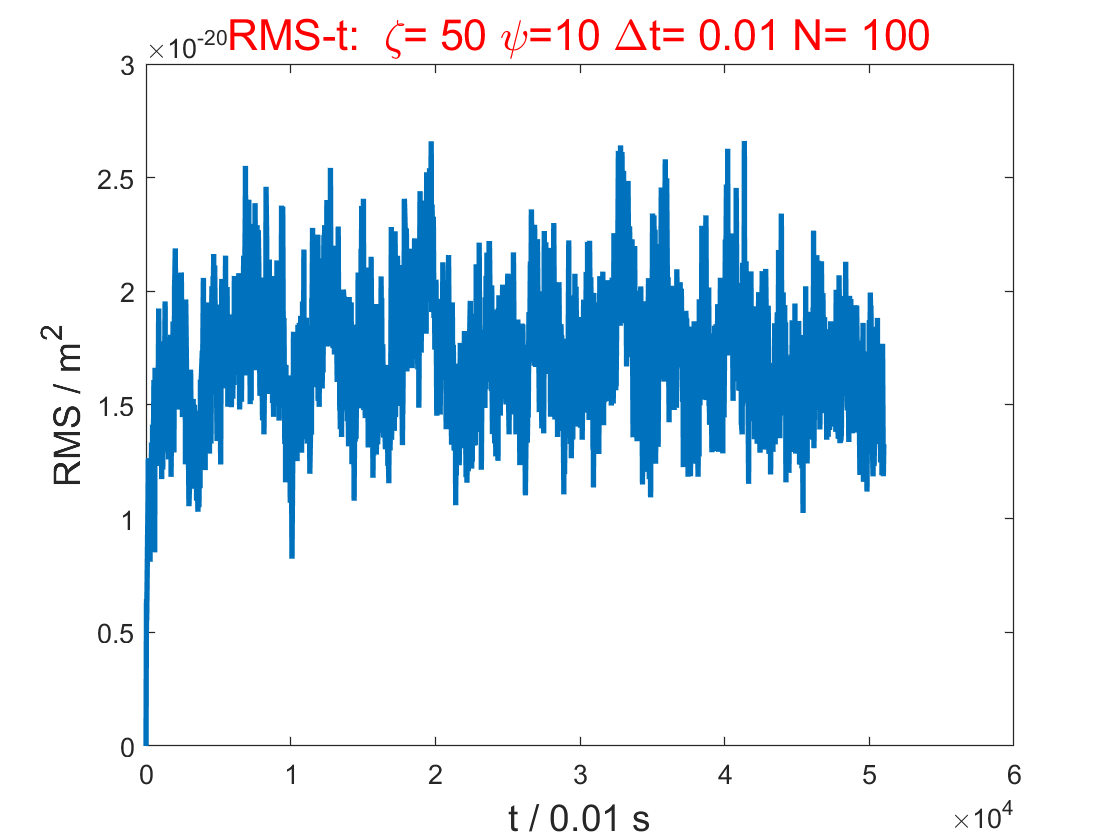

residual = 7.2296e+12

            residual=sum((simulation_RMSX(5*(1:Reserved_length))-interceptive_experiment_MSDX).^2)
        end
    end
end